## Open or consolidate data files

open the excel files with the test data to generate the database

clear
is_Mac = 0;
consolidate = 1;

if is_Mac
    save_path='/Users/tomasodeponti/Desktop/Flight data of VSQP/static_test_1805/database/general';
    data_path='/Users/tomasodeponti/Desktop/Flight data of VSQP/static_test_1805/database/single';
    addpath(genpath('/Users/tomasodeponti/Desktop/thesis/rot_wing_drone/sw')) %addpath(genpath('.\sw'))
else
    %save_path='C:\Users\Tomaso\Desktop\flight_data_VSQP\static_test_1805\database\general';
    %data_path='C:\Users\Tomaso\Desktop\flight_data_VSQP\static_test_1805\database\single';
    save_path='C:\Users\Tomaso\Desktop\flight_data_VSQP\static_test_1905\database\general';
    data_path='C:\Users\Tomaso\Desktop\flight_data_VSQP\static_test_1905\database\single';
    addpath(genpath('C:\Users\Tomaso\Desktop\Thesis\main\sw'))
end 
unit_header = ["ID","Item","Windspeed [m/s]","Airspeed [m/s]","Skew [deg]","Skew_sp [deg]","Mot_Status","Excitation","Mx [Nm]","My [Nm]","Mz [Nm]","Fx [N]","Fy[N]","Fz [N]","Mot_F [pwm]","Mot_R [pwm]","Mot_B [pwm]","Mot_L [pwm]","Ail_L [pwm]","Ail_R [pwm]","Elev [pwm]","Rud [pwm]","Pitch [deg]"];    
database_header = ["ID","Item","Windspeed","Airspeed","Skew","Skew_sp","Mot_Status","Excitation","Mx","My","Mz","Fx","Fy","Fz","Mot_F","Mot_R","Mot_B","Mot_L","Ail_L","Ail_R","Elev","Rud","Pitch"];
if consolidate
    xlsxFiles = dir(fullfile(data_path,'*.xlsx')); 
    numfiles = length(xlsxFiles);
    mydata = cell(1, numfiles);
    all    = [];
    for k = 1:numfiles 
      mydata{k} = xlsread(fullfile(data_path,xlsxFiles(k).name)); 
      all = [all;mydata{k}];
    end
    Table = array2table(all,'VariableNames',database_header);
    name = 'static_test_3.xlsx';
    table_path_format = fullfile(save_path,name);
    writetable(Table,table_path_format); 
else
    xlsxFiles = dir(fullfile(save_path,'*.xlsx'));
    all = xlsread(fullfile(save_path,xlsxFiles.name)); 
    Table = array2table(all,'VariableNames',database_header);
end


## Perform transformation from balance to drone c.g. and apply calibration

data = Table;

if is_Mac
    path = '/Users/tomasodeponti/Desktop/Flight data of VSQP/static_test_1605/OJF/calibration';
else
    path = 'C:\Users\Tomaso\Desktop\flight_data_VSQP\static_test_1905\OJF\calibration';
end
name = strcat('calibration.txt');
fid = fopen(fullfile(path,name));
format = sprintf('%s', repmat('%f', 1, 7));
calibration = cell2mat(textscan(fid, format,'Delimiter', ','));
fclose(fid);

for i =1:size(data,1)
    int_cal = interp1(calibration(:,1),calibration(:,2:end),data.Windspeed(i));
    data.Fx(i) = (data.Fx(i)-int_cal(1)).*(-1);
    data.Fy(i) = (data.Fy(i)-int_cal(2)).*(-1);
    data.Fz(i) = data.Fz(i)-int_cal(3);
    data.Mx(i) = (data.Mx(i)-int_cal(4)).*(-1);
    data.My(i) = (data.My(i)-int_cal(5)).*(-1);
    data.Mz(i) = data.Mz(i)-int_cal(6);
end

pole = [0,0,-1.2085].'; %[0,0,-1]90.5+5.5+8+16.85 -1.04
m_i  = [data.Mx,data.My,data.Mz];
f_i  = [data.Fx,data.Fy,data.Fz];
m_e  = m_i + cross(f_i,pole.'.*ones(size(f_i)));
data.Mx = m_e(:,1);
data.My = m_e(:,2);
data.Mz = m_e(:,3);
data2 = data;
% Rotated reference frame
data2.Fx = data.Fx;
data2.Fy = data.Fz;
data2.Fz = data.Fy.*(-1);
data2.Mx = data.Mx;
data2.My = data.Mz;
data2.Mz = data.My.*(-1);

## **Question to be answered**

*What is the CL curve of the drone at different pitch angles*

## Filter out not filled data points

data2 = data2(data2.Windspeed<16,:);
data2.Pitch = round(data2.Pitch);
data2.Skew_sp = max(data2.Skew_sp,0);
data2.Windspeed = round(data2.Windspeed);

## Investigate the lifting properties of the wing

lsqr converged at iteration 1 to a solution with relative residual 0.97.
lsqr stopped at iteration 50 without converging to the desired tolerance 1e-12
because the maximum number of iterations was reached.
The iterate returned (number 50) has relative residual NaN.
lsqr converged at iteration 1 to a solution with relative residual 0.56.
lsqr converged at iteration 1 to a solution with relative residual 0.52.
lsqr converged at iteration 1 to a solution with relative residual 0.49.
lsqr converged at iteration 1 to a solution with relative residual 0.77.
lsqr stopped at iteration 50 without converging to the desired tolerance 1e-12
because the maximum number of iterations was reached.
The iterate returned (number 50) has relative residual NaN.
lsqr converged at iteration 1 to a solution with relative residual 0.5.
lsqr converged at iteration 1 to a solution with relative residual 0.46.
lsqr stopped at iteration 50 without converging to the desired tolerance 1e-12
because the maximum numbe

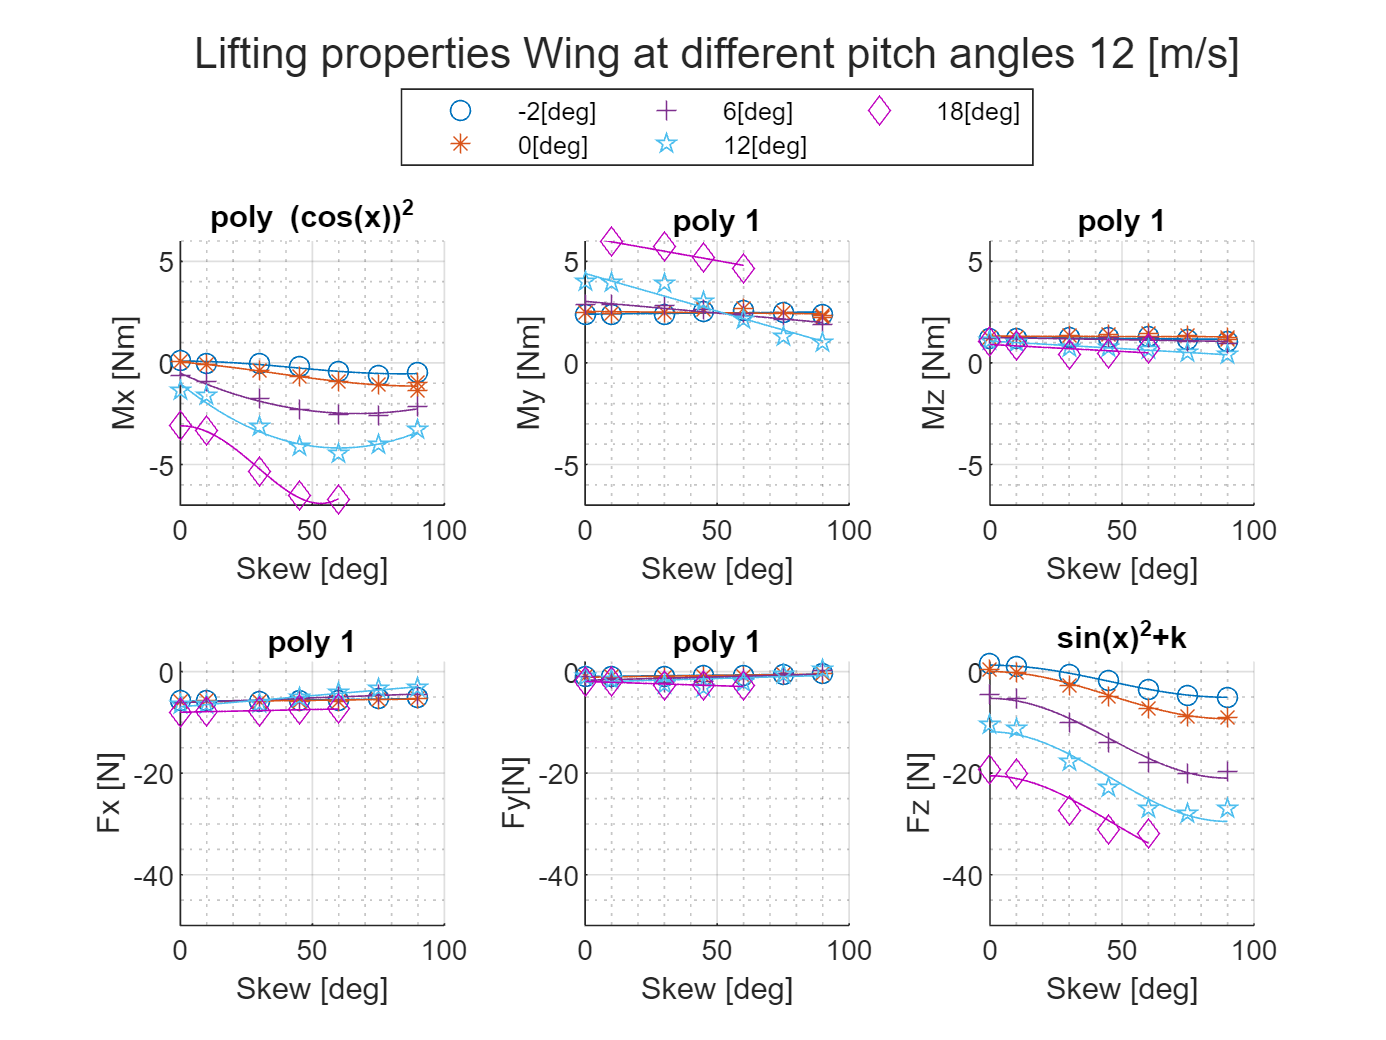

folder = fullfile(pwd,'plots_save');
baseline = 0 ;
baseline = baseline+k;
pitches = unique(round(data2.Pitch));
v = unique(data2.Windspeed);
%v_sel = v(3);
leg_pitch = [];
for i=[-2,0,6,12,18]
    leg_pitch= [leg_pitch,strcat(string(i),'[deg]'),''];
end
visible = 1;
save_pictures = 0;
for m=v(1:3).'
    if visible
      f=figure(baseline+k+1);
    else
      f=figure('visible','off');
    end
    clf
    cla
    t = tiledlayout(2,3);
    for j=9:14
        if  j==14
            order = 11; %11
        elseif j==9
            order = -1;
        else 
            order = 1;
        end
        nexttile
        hold on
        [tf, loc] = ismember([-2,0,6,12,18],pitches);
        for i=loc
            out  = table_sifter(data2,[-1,5,m,-1,-1,-1,0,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,pitches(i)]);
            temp = plot_special(out.(6),out.(j),order,i);
        end
        if j <12
            ylim([-7 6])
        else
            ylim([-50 2])
        end
        xlabel(unit_header(5))
        ylabel(unit_header(j))
        grid on
        grid minor
        hold off
    end
    lgd = legend(leg_pitch,'NumColumns',4);
    lgd.Layout.Tile = 'north';
    title(t,strcat('Lifting properties Wing at different pitch angles'," ",num2str(m),' [m/s]'))
    tit2 = strcat("Wing_pitch_study_v_",num2str(m));
    hold off
    if save_pictures
        saveas(f,fullfile(folder,strcat(tit2,'.jpg')))
    end
end

pitches = unique(round(data2.Pitch));
v = unique(data2.Windspeed);
leg_skew = [];
skews_sp = unique(data2.Skew_sp);
skews_sp(1) = 0;
L = 0.5 * 1.225 * 1.56 * 0.235 ;
h = zeros(size(skews_sp));
visible = 1;
save_pictures = 1;
if visible
  f=figure(20);
else
  f=figure('visible','off');
end
t = tiledlayout(1,1);
clf
cla
nexttile
hold on
for i=1:max(size(skews_sp))
    leg_skew= [leg_skew,strcat(string(skews_sp(i)),'[deg]'),''];
    out  = table_sifter(data2,[-1,5,-1,-1,-1,skews_sp(i),0,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1]);
    CL   = -1.*out.Fz./(L*out.Windspeed.^2);
    %temp = plot_special(out.Pitch,CL,-1,i);
    [rmse_log,p_out,h] =plot_special_v2(out.Pitch,CL,-1,i,1,h);
end

lsqr converged at iteration 1 to a solution with relative residual 0.17.
lsqr converged at iteration 1 to a solution with relative residual 0.17.
lsqr converged at iteration 1 to a solution with relative residual 0.25.
lsqr converged at iteration 1 to a solution with relative residual 0.31.
lsqr converged at iteration 1 to a solution with relative residual 0.39.
lsqr converged at iteration 1 to a solution with relative residual 0.46.
lsqr stopped at iteration 50 without converging to the desired tolerance 1e-12
because the maximum number of iterations was reached.
The iterate returned (number 50) has relative residual NaN.


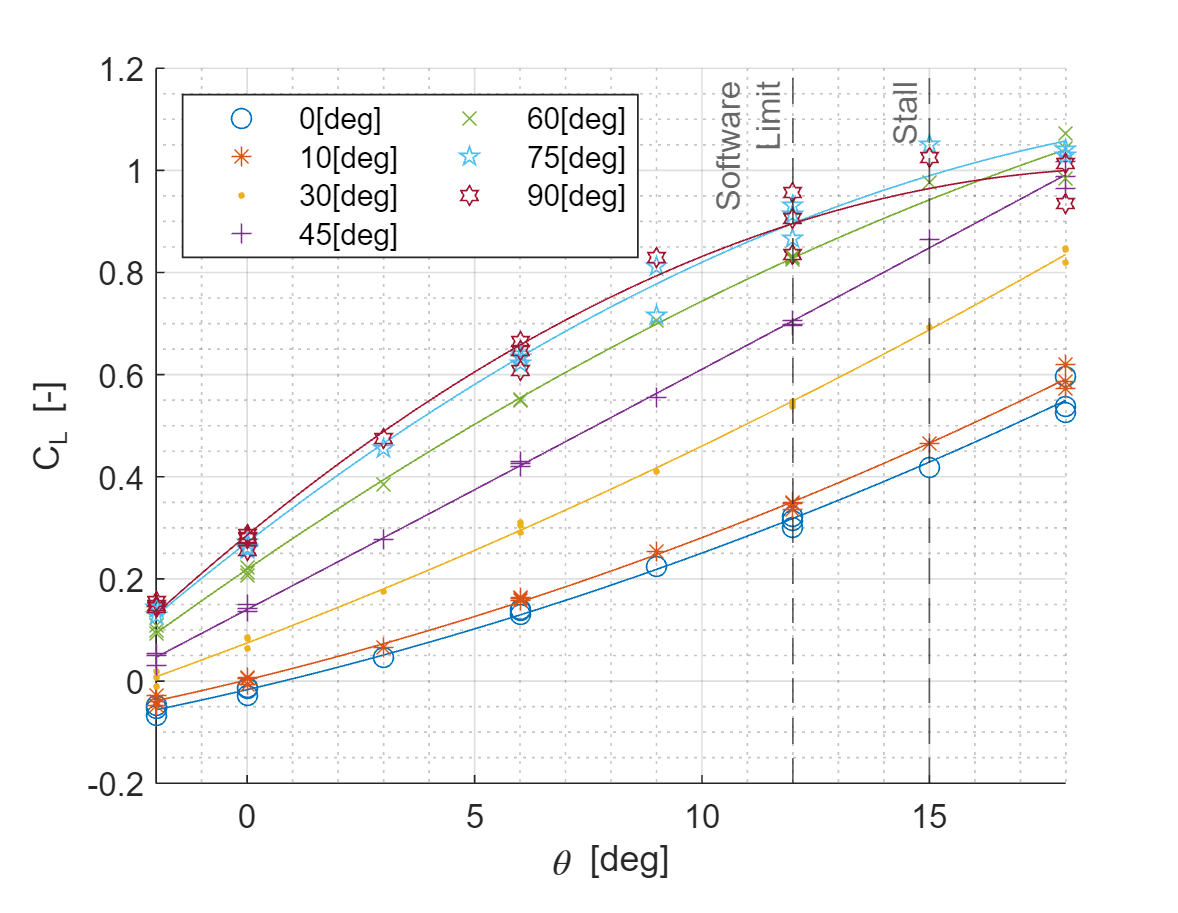

xline([12 15],'--',{{'Software';'Limit'},'Stall'},'LabelHorizontalAlignment','left','LabelVerticalAlignment',{'top'})
xlabel("\theta [deg]")
xlim([-2,18])
ylabel("C_L [-]")
grid on
grid minor
f.Units = 'inches';
f.OuterPosition = [0 0 5 4];
lgd = legend(leg_skew,'NumColumns',2,'Location','northwest');
%lgd.Layout.Tile = 'north';
%title('C_L curve at different skew angles')
s = strcat("Wing_CL_curve");
if save_pictures
    %saveas(f,fullfile(folder,strcat(tit2,'.jpg')))
    %paper_plot(3,3,gcf,fullfile(folder,strcat(tit2,'.pdf')))
    exportgraphics(f,fullfile(folder,strcat(s,'.pdf')),'ContentType','vector')
    %export_fig(fullfile(folder,strcat(tit2,'.jpg')),'-transparent')
end

## Wing lift study

lsqr converged at iteration 3 to a solution with relative residual 0.16.
lsqr converged at iteration 6 to a solution with relative residual 0.13.
lsqr converged at iteration 12 to a solution with relative residual 0.13.
lsqr converged at iteration 20 to a solution with relative residual 0.13.
lsqr converged at iteration 33 to a solution with relative residual 0.13.
lsqr converged at iteration 1 to a solution with relative residual 0.36.
lsqr converged at iteration 1 to a solution with relative residual 0.48.
lsqr converged at iteration 1 to a solution with relative residual 0.62.
lsqr converged at iteration 2 to a solution with relative residual 0.19.
lsqr converged at iteration 2 to a solution with relative residual 0.27.
lsqr converged at iteration 3 to a solution with relative residual 0.32.
lsqr converged at iteration 2 to a solution with relative residual 0.24.
lsqr converged at iteration 2 to a solution with relative residual 0.36.
lsqr converged at iteration 3 to a solution with

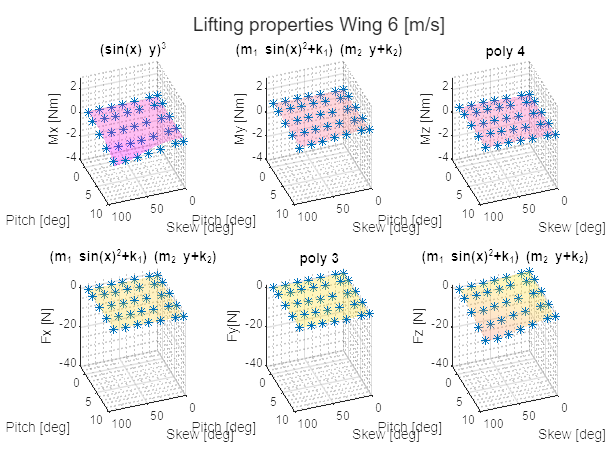

lsqr converged at iteration 3 to a solution with relative residual 0.19.
lsqr converged at iteration 6 to a solution with relative residual 0.16.
lsqr converged at iteration 10 to a solution with relative residual 0.16.
lsqr converged at iteration 14 to a solution with relative residual 0.16.
lsqr converged at iteration 20 to a solution with relative residual 0.16.
lsqr converged at iteration 1 to a solution with relative residual 0.62.
lsqr converged at iteration 1 to a solution with relative residual 0.52.
lsqr converged at iteration 1 to a solution with relative residual 0.61.
lsqr converged at iteration 2 to a solution with relative residual 0.16.
lsqr converged at iteration 2 to a solution with relative residual 0.28.
lsqr converged at iteration 3 to a solution with relative residual 0.25.
lsqr converged at iteration 2 to a solution with relative residual 0.29.
lsqr converged at iteration 2 to a solution with relative residual 0.35.
lsqr converged at iteration 3 to a solution with

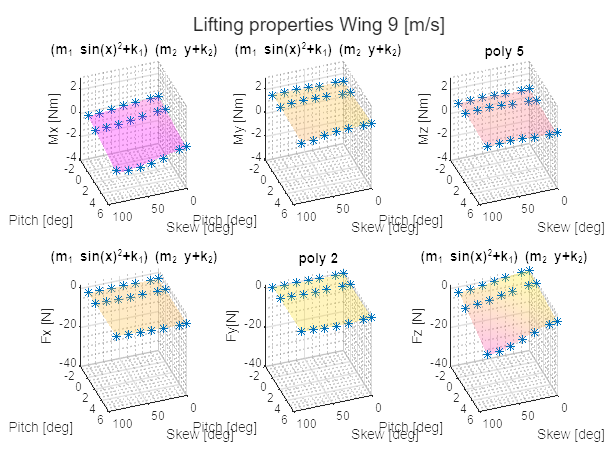

lsqr converged at iteration 3 to a solution with relative residual 0.22.
lsqr converged at iteration 6 to a solution with relative residual 0.18.
lsqr converged at iteration 11 to a solution with relative residual 0.15.
lsqr converged at iteration 16 to a solution with relative residual 0.15.
lsqr converged at iteration 27 to a solution with relative residual 0.15.
lsqr converged at iteration 1 to a solution with relative residual 0.51.
lsqr stopped at iteration 50 without converging to the desired tolerance 1e-12
because the maximum number of iterations was reached.
The iterate returned (number 50) has relative residual NaN.
lsqr converged at iteration 1 to a solution with relative residual 0.61.
lsqr converged at iteration 2 to a solution with relative residual 0.21.
lsqr converged at iteration 3 to a solution with relative residual 0.24.
lsqr converged at iteration 3 to a solution with relative residual 0.27.
lsqr converged at iteration 2 to a solution with relative residual 0.28.
l

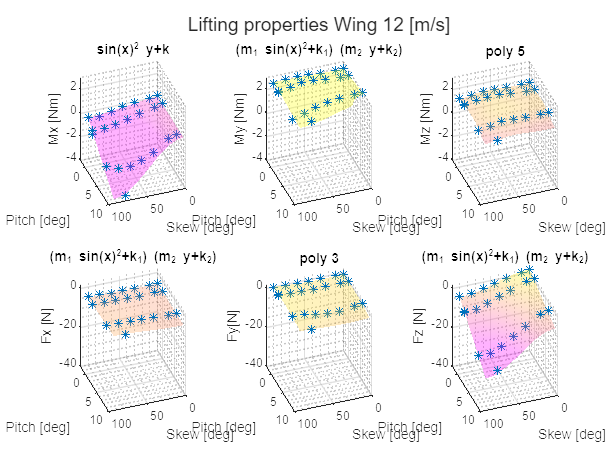

pitches = unique(round(data2.Pitch));
v = unique(data2.Windspeed);
leg_skew = [];
skews_sp = unique(data2.Skew_sp);
skews_sp(1) = 0;
L = 0.5 * 1.225 * 1.56 * 0.235 ;
visible = 1;
save_pictures = 1;
v = unique(data2.Windspeed);
skew_q = unique(data2.Skew_sp);
rmse_log = {};
coeffs = {};
for m=1:max(size(v))
    if visible
      f=figure(25+m);
    else
      f=figure('visible','off');
    end
    
    clf
    cla
    t = tiledlayout(2,3);
    for j=9:14
        nexttile
        prefilter = data2(data2.Pitch<12,:);
        if j==14
            order = 24;%13
        else
            order = -1;
        end
        out  = table_sifter(prefilter,[-1,5,v(m),-1,-1,-1,0,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1]);
        [rmse_log_i,coeffs_i] = plot3_special(out.(6),out.(23),out.(j),order,2);
        rmse_log{m}{j-8} = rmse_log_i;
        coeffs{m}{j-8}   = coeffs_i;
        if j <12
            zlim([-4 3])
            caxis([-0.5,2])
        else
            zlim([-40 2])
            caxis([-17,2])
        end
        xlabel(unit_header(5))
        ylabel(unit_header(23))
        zlabel(unit_header(j))    
        grid on
        grid minor
        view([160 30])
        hold off
    end
    x_width= 40 ;
    y_width= 30 ;
    set(f, 'PaperPosition', [0 0 x_width y_width]);
    title(t,strcat("Lifting properties Wing ",num2str(v(m))," [m/s]"))
    tit2 = strcat("Wing_pitch_skew_study_3D_v_",num2str(v(m)));
    hold off
    if save_pictures
        saveas(f,fullfile(folder,strcat(tit2,'.jpg')))
    end
end

pitches = unique(round(data2.Pitch));
v = unique(data2.Windspeed);
leg_skew = [];
skews_sp = unique(data2.Skew_sp);
skews_sp(1) = 0;
L = 0.5 * 1.225 * 1.56 * 0.235 ;
visible = 1;
save_pictures = 1;
v = unique(data2.Windspeed);
skew_q = unique(data2.Skew_sp);
rmse_log = {};
coeffs = {};
if visible
      f=figure(30);
else
      f=figure('visible','off');
end
clf
cla
t = tiledlayout(1,3);
for m=1:max(size(v))
    for j=14
        nexttile
        prefilter = data2(data2.Pitch<12,:);
        if j==14
            order = 24;%13
        else
            order = -1;
        end
        out  = table_sifter(prefilter,[-1,5,v(m),-1,-1,-1,0,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1]);
        [rmse_log_i,coeffs_i] = plot3_special(out.(6),out.(23),out.(j),order,2);
        rmse_log{m}{j-8} = rmse_log_i;
        coeffs{m}{j-8}   = coeffs_i;
        if j <12
            zlim([-4 3])
            caxis([-0.5,2])
        else
            zlim([-40 2])
            caxis([-17,2])
        end
        xlabel(unit_header(5))
        ylabel(unit_header(23))
        zlabel(unit_header(j)) 
        title({strcat(num2str(v(m))," [m/s]");"(m_1 sin(x)^2+k_1) (m_2 y+k_2)"})
        grid on
        grid minor
        view([160 30])
        hold off
    end
end

lsqr converged at iteration 5 to a solution with relative residual 0.03.
lsqr converged at iteration 5 to a solution with relative residual 0.03.
lsqr converged at iteration 5 to a solution with relative residual 0.03.
lsqr converged at iteration 5 to a solution with relative residual 0.03.
lsqr converged at iteration 5 to a solution with relative residual 0.03.
lsqr converged at iteration 5 to a solution with relative residual 0.03.
lsqr converged at iteration 5 to a solution with relative residual 0.03.
lsqr converged at iteration 5 to a solution with relative residual 0.03.
lsqr converged at iteration 5 to a solution with relative residual 0.03.
lsqr converged at iteration 5 to a solution with relative residual 0.03.
lsqr converged at iteration 5 to a solution with relative residual 0.03.
lsqr converged at iteration 5 to a solution with relative residual 0.03.
lsqr converged at iteration 5 to a solution with relative residual 0.03.
lsqr converged at iteration 5 to a solution with re

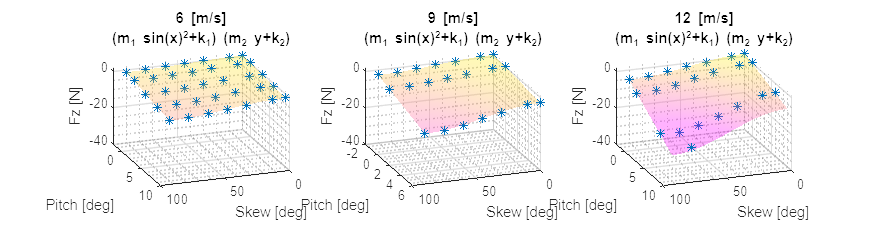

x_width= 30 ;
y_width= 10 ;
set(f, 'PaperPosition', [0 0 x_width y_width]);
%title(t,strcat("Lift"))
tit2 = strcat("Wing_pitch_skew_study_3D_all_v");
hold off
if save_pictures
    saveas(f,fullfile(folder,strcat(tit2,'.jpg')))
end

Save each single image

pitches = unique(round(data2.Pitch));
v = unique(data2.Windspeed);
leg_skew = [];
skews_sp = unique(data2.Skew_sp);
skews_sp(1) = 0;
L = 0.5 * 1.225 * 1.56 * 0.235 ;
visible = 1;
save_pictures = 0;
v = unique(data2.Windspeed);
skew_q = unique(data2.Skew_sp);
rmse_log = {};
coeffs = {};
if visible
      f=figure(30);
else
      f=figure('visible','off');
end
clf
cla
t = tiledlayout(1,3,'TileSpacing','loose');
for m=1:max(size(v))
    for j=14
        nexttile
        prefilter = data2(data2.Pitch<12,:);
        if j==14
            order = 24;%13
        else
            order = -1;
        end
        out  = table_sifter(prefilter,[-1,5,v(m),-1,-1,-1,0,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1]);
        [rmse_log_i,coeffs_i] = plot3_special(out.(6),out.(23),out.(j),order,2);
        rmse_log{m}{j-8} = rmse_log_i;
        coeffs{m}{j-8}   = coeffs_i;
        if j <12
            zlim([-4 3])
            caxis([-0.5,2])
        else
            zlim([-40 2])
            caxis([-17,2])
        end
        xlabel(unit_header(5))
        ylabel(unit_header(23))
        zlabel(unit_header(j)) 
        title({strcat(num2str(v(m))," [m/s]");"(m_1 sin(x)^2+k_1) (m_2 y+k_2)"})
        grid on
        grid minor
        view([160 30])
        hold off
        
    end
end

lsqr converged at iteration 5 to a solution with relative residual 0.03.
lsqr converged at iteration 5 to a solution with relative residual 0.03.
lsqr converged at iteration 5 to a solution with relative residual 0.03.
lsqr converged at iteration 5 to a solution with relative residual 0.03.
lsqr converged at iteration 5 to a solution with relative residual 0.03.
lsqr converged at iteration 5 to a solution with relative residual 0.03.
lsqr converged at iteration 5 to a solution with relative residual 0.03.
lsqr converged at iteration 5 to a solution with relative residual 0.03.
lsqr converged at iteration 5 to a solution with relative residual 0.03.
lsqr converged at iteration 5 to a solution with relative residual 0.03.
lsqr converged at iteration 5 to a solution with relative residual 0.03.
lsqr converged at iteration 5 to a solution with relative residual 0.03.
lsqr converged at iteration 5 to a solution with relative residual 0.03.
lsqr converged at iteration 5 to a solution with re

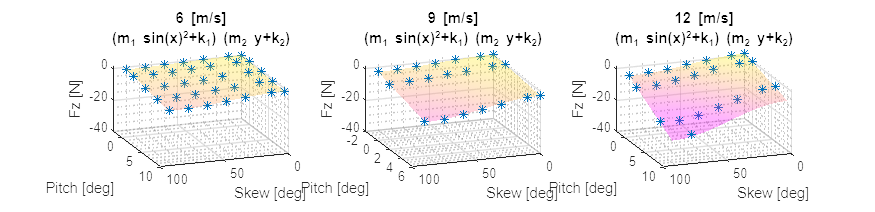

% x_width= 30 ;
% y_width= 10 ;
% set(f, 'PaperPosition', [0 0 x_width y_width]);
f.Units = 'inches';
f.OuterPosition = [0.25 0.25 15 4];
%title(t,strcat("Lift"))
tit2 = strcat("Wing_pitch_skew_study_3D_all_v");
hold off

if save_pictures
    %saveas(f,fullfile(folder,strcat(tit2,'.jpg')))
    %paper_plot(3,6,gcf,fullfile(folder,strcat(tit2,'.pdf')))
    export_fig(fullfile(folder,strcat(tit2,'.pdf')))
end

## Lift model for controller

out  = table_sifter(prefilter,[-1,5,-1,-1,-1,-1,0,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1]);
%v 1/2 rho S (m theta + k) (sin(Lambda) v)^2
% p = [L.*(sin(deg2rad(out.Skew_sp)).*out.Windspeed).^2.*deg2rad(out.Pitch),L.*(sin(deg2rad(out.Skew_sp)).*out.Windspeed).^2]\out.(14);
% RMSE = rms(out.(14)-(p(1).*L.*(sin(deg2rad(out.Skew_sp)).*out.Windspeed).^2.*deg2rad(out.Pitch)+p(2).*L.*(sin(deg2rad(out.Skew_sp)).*out.Windspeed).^2));

% p = [L.*(sin(deg2rad(out.Skew_sp)).*out.Windspeed).^2.*deg2rad(out.Pitch),L.*(sin(deg2rad(out.Skew_sp)).*out.Windspeed).^2,ones(size(out.Skew_sp))]\out.(14);
% RMSE = rms(out.(14)-(p(1).*L.*(sin(deg2rad(out.Skew_sp)).*out.Windspeed).^2.*deg2rad(out.Pitch)+p(2).*L.*(sin(deg2rad(out.Skew_sp)).*out.Windspeed).^2+p(3)));

gamma = L.*out.Windspeed.^2;
skew_f = deg2rad(out.Skew_sp);
pitch_f = deg2rad(out.Pitch);
p = gamma.*[pitch_f.*sin(skew_f).^2,sin(skew_f).^2,pitch_f,ones(size(skew_f))]\out.(14);
est = gamma.*(p(1).*pitch_f.*sin(skew_f).^2+p(2).*sin(skew_f).^2+p(3).*pitch_f+p(4).*ones(size(skew_f)));
RMSE = rms(out.(14)-est);